# Example 4.1: `Maximum Detection Range of a ``3G` `CDMA`` Signal`

Nicholas O'Donoughue 1 July 2019

*Consider the parameters in Table 4.1a for both a handset user as well as the base station of a **3G* *CDMA** cell phone network. Parameters for a receiver mounted on a low-flying aircraft are  given in Table 4.1b.*

*What is the maximum range at which an energy detector and a cross-correlation detector can detect the tower and the handset?  For simplicity, assume that they are the only two users transmitting. Assume that the maximum acceptable *$$P_{\mathrm{FA}}$$* is *$$10^{-6}$$* and that the desired *$$P_{\mathrm{D}}$$* is 0.8.*

## `Solution`

First, we define the parameters

% Transmit Parameters
ERP = [10, -7]; % dBW [tower, user]
f0 = [850000000, 1900000000]; % Hz [tower, user]
ht = [60, 2]; % m [tower, user]
Lt = 0; % dB, transmit loss
Bs = 5000000; % Hz, single channel bandwidth
Tp = 0.02; % s, pulse duration

% Receive Side
hr = 1000; % m, receiver alt
Gr = 0; % dB, receive antenna gain
Lr = 3; % dB, receiver losses
NF = 5; % dB, receiver noise figure
Bn = 100000000; % Hz, receiver channel bandwidth
Tcorr = 0.0001; % s, duration of cross-correlation window


Next, we assemble the reference SNR ($$\xi_0$$) according to (3.39). 

% Compute Initial SNR (without any propagation loss)
N0 = utils.constants.boltzmann*utils.constants.T0*10^(NF/10);
N = 10*log10(N0*Bn);
xi0 = ERP + Gr - Lt - Lr - N

xi0 =   125.9753  108.9753


Next, we compute the propagation losses and received SNR for both a tower transmission and user handset transmission. Then we compute the SNR as a function of range.

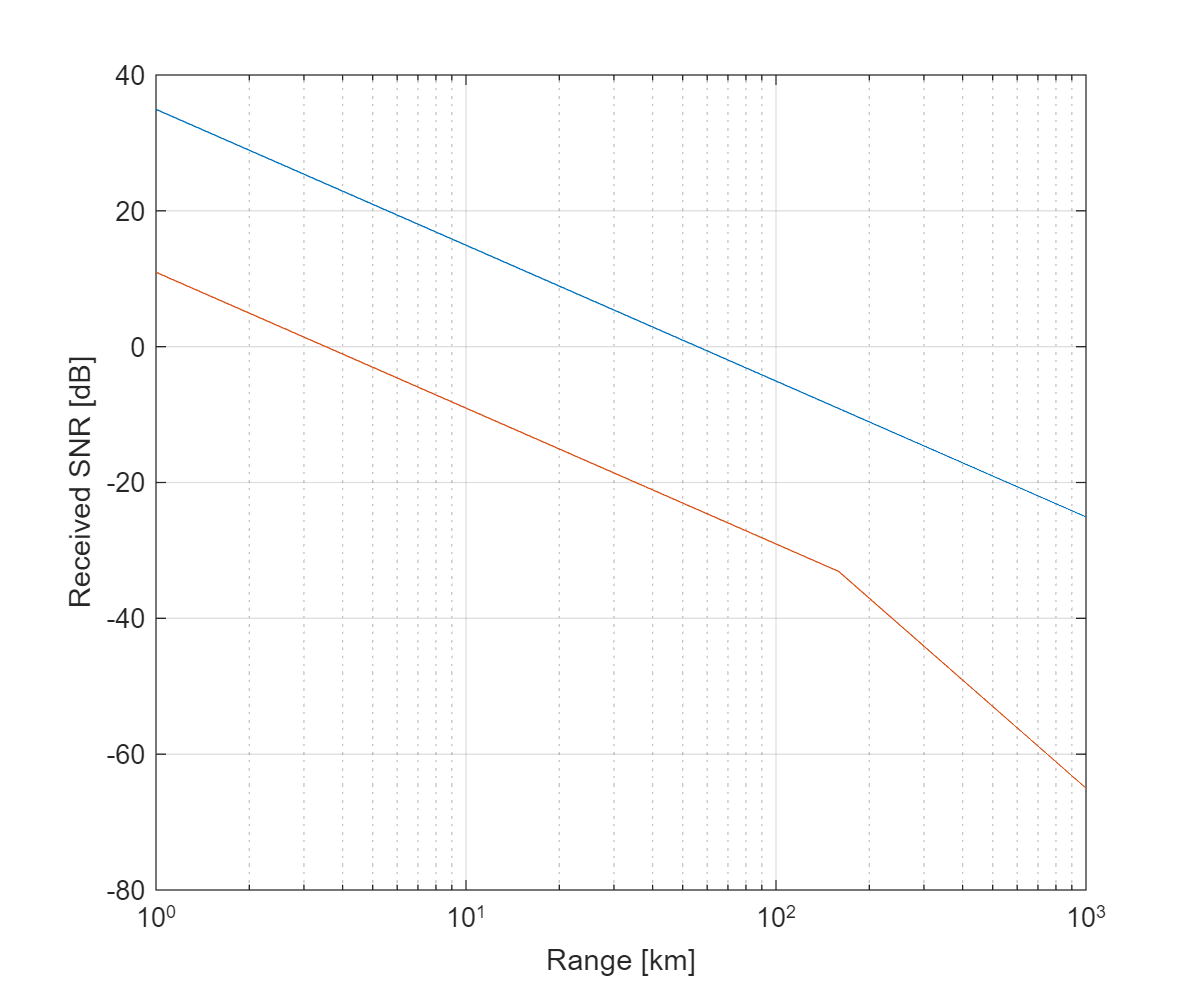

% Compute Prop Loss
rng_min_km = 1;
rng_max_km = 1000;
rng_spacing_km = 1;
Rvec = (rng_min_km:rng_spacing_km:rng_max_km)*1e3; % m, range vector

Lprop_twr = prop.pathLoss(Rvec,f0(1),ht(1),hr,false);
Lprop_user= prop.pathLoss(Rvec,f0(2),ht(2),hr,false);

xi_twr = xi0(1) - Lprop_twr;
xi_user = xi0(2) -Lprop_user;

figure;
plot(Rvec/1e3,xi_twr,'DisplayName','Tower');
hold on;
plot(Rvec/1e3,xi_user,'DisplayName','User');
xlabel('Range [km]');
ylabel('Received SNR [dB]');
set(gca,'xscale','log');
grid on;

Note the change in received SNR for the user terminal at ranges beyond 100 km.  This is due to a shift from free space propagation to two-ray, as we extend past the Fresnel Zone.

Next, we set up the detector by specifying $P_D$ and $P_{FA}$, and compute the required SNR for an Energy Detector and a Cross-Correlation Detector.  `For the energy detector, we compute `$$\eta$$` and `$$P_{\mathrm{D}}$$` using (3.25) and (3.26), respectively, with the function detector.squareLawMinSNR. `

% Compute thresholds
PD=0.8;
PFA=0.000001;
M = fix(Tcorr*Bn);
xi_ed = detector.squareLawMinSNR(PFA,PD,M)

xi_ed = -12.4298

For the cross-correlation detector, we can apply the SNR gain equation from (4.20) to determine that an input SNR of $$\xi_i=-19.66$$ dB is sufficient to achieve the required -12.43 dB SNR after cross-correlation processing, an improvement of 7.2 dB. This can alternatively be computed with the script

xi_xc = detector.xcorrMinSNR(PFA,PD,Tcorr,Tp,Bn,Bs)

xi_xc = -19.6633

With the derived SNR thresholds, we can compute (analytically) the maximum range, and then overlay onto a plot of SNR vs. distance to confirm. 

% Compute Max Range
R_twr_ed = detector.squareLawMaxRange(PFA,PD,M,f0(1),ht(1),hr,xi0(1),false,[]);
R_user_ed = detector.squareLawMaxRange(PFA,PD,M,f0(2),ht(2),hr,xi0(2),false,[]);
R_twr_xc = detector.xcorrMaxRange(PFA,PD,Tcorr,Tp,Bn,Bs,f0(1),ht(1),hr,xi0(1),false,[]);
R_user_xc = detector.xcorrMaxRange(PFA,PD,Tcorr,Tp,Bn,Bs,f0(2),ht(2),hr,xi0(2),false,[]);

fprintf('Detection range of tower\n\tusing Energy Detector: %.2f km\n\tusing Cross Correlator: %.2f km\n',R_twr_ed/1e3,R_twr_xc/1e3);

Detection range of tower
	using Energy Detector: 233.46 km
	using Cross Correlator: 537.18 km


fprintf('Detection range of handset user\n\tusing Energy Detector: %.2f km\n\tusing Cross Correlator: %.2f km\n',R_user_ed/1e3,R_user_xc/1e3);

Detection range of handset user
	using Energy Detector: 14.76 km
	using Cross Correlator: 33.93 km


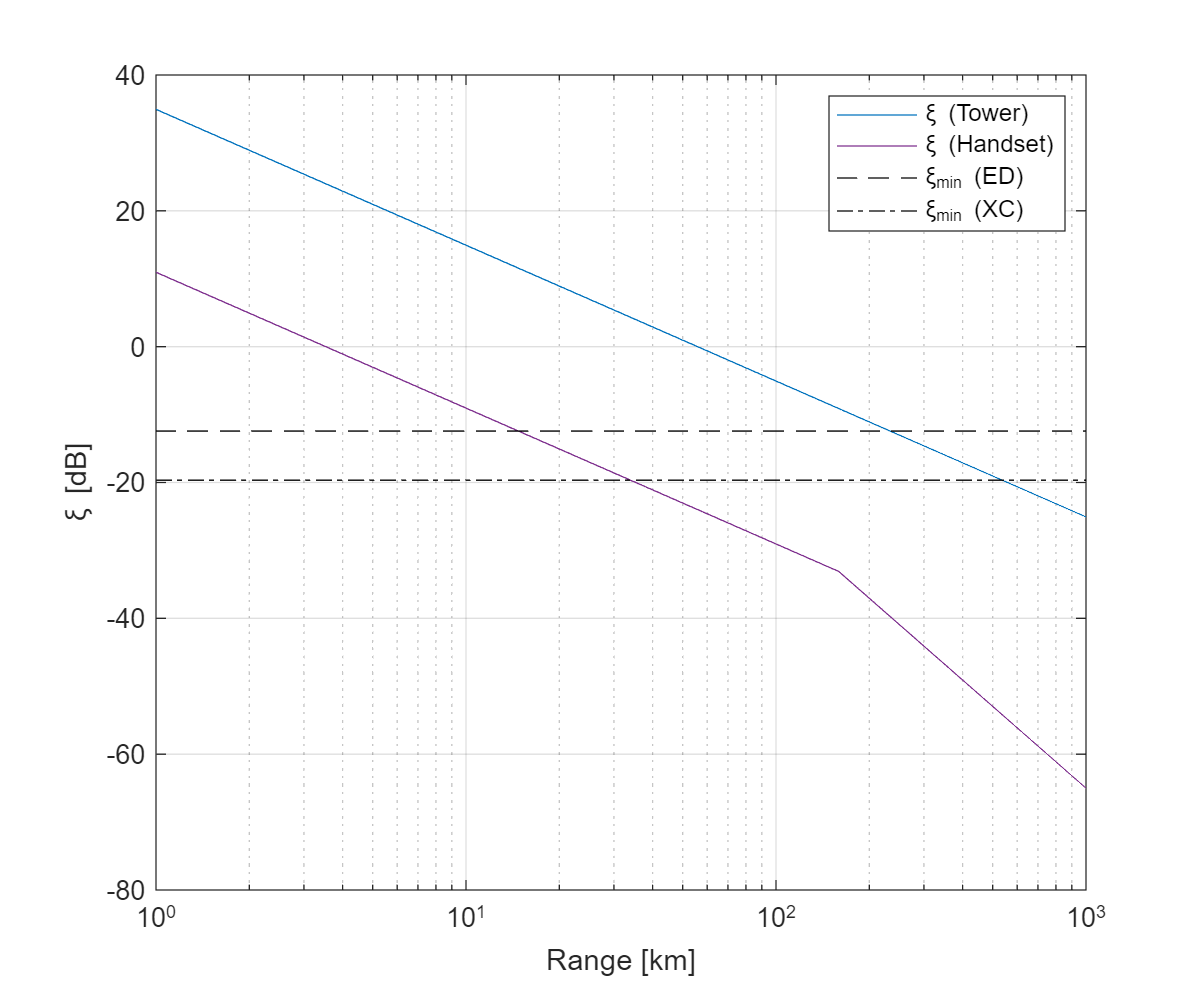


% Plot results
fig=figure;
semilogx(Rvec/1e3,xi_twr,'DisplayName','\xi (Tower)');hold on;
set(gca,'ColorOrderIndex',4);
plot(Rvec/1e3,xi_user,'DisplayName','\xi (Handset)');
plot(Rvec([1 end])/1e3,xi_ed*[1 1],'k--','DisplayName','\xi_{min} (ED)');
plot(Rvec([1 end])/1e3,xi_xc*[1 1],'k-.','DisplayName','\xi_{min} (XC)');
legend;
grid on;
xlabel('Range [km]');
ylabel('\xi [dB]');